## Particle Swarm Optimization for Maximum of a Function 

## Function:     f(x) = -x^2 + x + 7

clf(figure);
clear;

% Define the function to maximize
func = @(x) -x.^2 + x + 7;  % Maximum is at x = 0 with f(x) = 4

## Initialization

For User Input, Run this Section:

num_particles = input('Enter the Swarm Size: ');
iterations = input('Enter the Iterations: ');
w = input('Enter the Inertia weight: ');% 
c1 = input('Enter the Cognitive coefficient: '); % 
c2 = input('Enter the Social coefficient: '); % 
lower_x_bound = input('Enter the lower bound for x : ');
upper_x_bound = input('Enter the upper bound for x : ');

% Define search space boundaries


For Default Value Run this Section:

Swarm size: 5

Iterations: 50

Dimension: 1

Cognitive coeffficeint: 1.5

Social Coefficient: 1.5

Moment of Inetria: 0.5

% PSO parameters
num_particles = 4;
iterations = 30;
w = 0.5;  % Inertia weight
c1 = 1.5; % Cognitive coefficient
c2 = 1.5; % Social coefficient

lower_x_bound = -5;
upper_x_bound = 5;

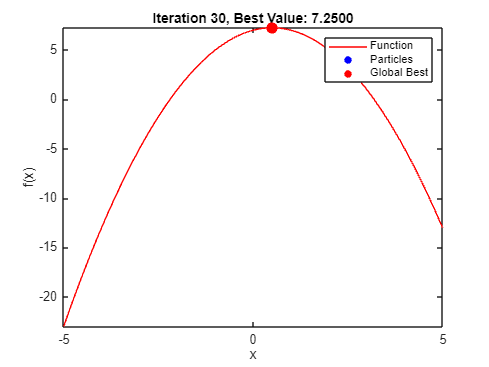


% Initialize particle positions and velocities
positions = lower_x_bound + 2 * upper_x_bound * rand(num_particles, 1); % Random initial values within [-x_bound, x_bound]
velocities = -1 + 2 * rand(num_particles, 1); % Initialize random velocities

% Initialize personal bests
personal_best_positions = positions;
personal_best_scores = arrayfun(func, positions);

% Initialize global best
[global_best_score, idx] = max(personal_best_scores);
global_best_position = personal_best_positions(idx);

% Set up the figure for visualization
figure;
fplot(func, [lower_x_bound, upper_x_bound], 'r'); % Plot the function
hold on;
title('Particle Swarm Optimization for Maximizing Function');
xlabel('x');
ylabel('f(x)');
particles_plot = scatter(positions, func(positions), 50, 'filled', 'MarkerFaceColor', 'blue'); % Particles
global_best_plot = scatter(global_best_position, global_best_score, 80, 'filled', 'MarkerFaceColor', 'red'); % Global best
legend('Function', 'Particles', 'Global Best');

% PSO main loop
for iter = 1:iterations
    % Update personal and global bests
    for j = 1:num_particles
        % Calculate current score
        current_position = positions(j);
        current_score = func(current_position);

        % Update personal best
        if current_score > personal_best_scores(j)
            personal_best_scores(j) = current_score;
            personal_best_positions(j) = current_position;
        end

        % Update global best
        if current_score > global_best_score
            global_best_score = current_score;
            global_best_position = current_position;
        end
    end

    % Update velocities and positions
    for j = 1:num_particles
        r1 = rand();
        r2 = rand();
        velocities(j) = w * velocities(j) ...
            + c1 * r1 * (personal_best_positions(j) - positions(j)) ...
            + c2 * r2 * (global_best_position - positions(j));
        positions(j) = positions(j) + velocities(j);

        % Ensure positions stay within bounds
        positions(j) = max(min(positions(j), upper_x_bound), lower_x_bound);
    end

    % Update the plot
    set(particles_plot, 'XData', positions, 'YData', func(positions));
    set(global_best_plot, 'XData', global_best_position, 'YData', global_best_score);
    title(sprintf('Iteration %d, Best Value: %.4f', iter, global_best_score));
    pause(0.5); % Pause for visualization
end


fprintf('Optimal x: %.4f\n', global_best_position);

Optimal x: 0.5000


fprintf('Maximum Value: %.4f\n', global_best_score);

Maximum Value: 7.2500
